#  Neurosynth topic maps for Emotion Regulation

**Purpose: **This script analyzes Emotion Generation maps from AHAB and PIP datasets (Gianaros P01 data) using Neurosynth topic and term (feature set) maps. 

**Authors**: Ke Bo & Tor Wager

**Date**: 1/2022

**Define paths and load data**

clear
basedir = 'D:\CANlab_Working\BF_Mat\';
% basedir = '/Users/f003vz1/Dropbox (Dartmouth College)/A1_WORKING_ANALYSES/2021_Ke_Bo_reappraisal_Gianaros';

cd(basedir)
datadir = fullfile(basedir, 'Data', 'BF_Maps');
datadir=''


datadir =

  0×0 empty char array



savefilename = 'Combined_001_3mm_Multiply_BF_4_6_WithoutRest3_Beta_WithoutSTS_NewBase_CC15.mat';
 
load(fullfile(datadir, savefilename))



    Temp=BF_tstat1_CC.dat;
    Index=find(Temp==0);
    BF_tstat1_CC.dat(Index)=0.0000001;
    
    Temp=BF_tstat2_CC.dat;
    Index=find(Temp==0);
    BF_tstat2_CC.dat(Index)=0.0000001;
    
    Temp=BF_tstat3_CC.dat;
    Index=find(Temp==0);
    BF_tstat3_CC.dat(Index)=0.0000001;
    
    Temp=BF_tstat4_CC.dat;
    Index=find(Temp==0);
    BF_tstat4_CC.dat(Index)=0.0000001;





Common_Appraisal=fmri_data(BF_tstat1_CC);

Number of unique values in dataset: 2  Bit rate: 1.00 bits


Reappraisal_Only=fmri_data(BF_tstat2_CC);

Number of unique values in dataset: 2  Bit rate: 1.00 bits


Non_Modificable_Emo_Gen=fmri_data(BF_tstat3_CC);

Number of unique values in dataset: 2  Bit rate: 1.00 bits


Modificable_Emo_Gen=fmri_data(BF_tstat4_CC);

Number of unique values in dataset: 2  Bit rate: 1.00 bits



emo_maps = cat(Common_Appraisal, Reappraisal_Only, Non_Modificable_Emo_Gen, Modificable_Emo_Gen);

colors = {[0 .5 1] [0 0 1] [1 0 0] [1 .5 0]};
names = {'CommApr' 'Reapp' 'UnModEmo' 'ModEmo'};

## Neurosynth feature set analyses

% Display helper functions: Called by later scripts
% --------------------------------------------------------

dashes = '----------------------------------------------';
printstr = @(dashes) disp(dashes);
printhdr = @(str) fprintf('%s\n%s\n%s\n', dashes, str, dashes);


### Common Appraisal

% printhdr('Top topics for Common Appraisal')
% figure; axis off; montage(Common_Appraisal);
% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels(Common_Appraisal, 'images_are_replicates', false, 'topk', 20, 'noverbose');

### Reappraisal Only

% printhdr('Top topics for Reappraisal Only')
% figure; axis off; montage(Reappraisal_Only);
% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels(Reappraisal_Only, 'images_are_replicates', false, 'topk',40, 'noverbose');

### Non-Modifiable Emotion Generation

% printhdr('Top topics for Non-Modifiable Emotion Generation')
% figure; axis off; montage(Non_Modificable_Emo_Gen);
% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels(Non_Modificable_Emo_Gen, 'images_are_replicates', false, 'topk', 20, 'noverbose');

### Modifiable Emotion Generation (Reappraisal targets)

% printhdr('Top topics for Modifiable Emotion Generation')
% figure; axis off; montage(Modificable_Emo_Gen);
% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels(Modificable_Emo_Gen, 'images_are_replicates', false, 'topk', 20, 'noverbose');

## Neurosynth topic analyses

Topic maps developed by Tal Yarkoni (Yarkoni 2014) are available from **Neurosynth.org**. A topic set containing 100 topics is in the CANlab Github **Neuroimaging_pattern_masks** repository. It includes the file "Neurosynth_Topics_v4-topics-100.csv", which is used to identify whether the topic folder is on the Matlab path.

"v4_topics" is a set of 100 topics extracted with LDA from the abstracts of all articles in the Neurosynth database as of July 2015 (11,406 articles). Some of these are related primarily to anatomical terms. A set of 42 interesting topic maps related to psychological terms was selected based on including mainly psychological content terms by Tor Wager.

**Forward and reverse inference maps**

In Neurosynth maps,  **pAgF** denotes probability of activation given topic ('forward inference'). **pFgA** denotes probability of topic given activation ('reverse inference'). Note that the 'reverse inference' maps do not guarantee specificity, as they reflect merely a greater probability that a map belongs to a topic than not given activation in significant voxels; this is determined with an association (chi-square) test not a multi-way classification test. Nonetheless, 'reverse inference' maps tend to be more spatially localized than 'forward inference' maps.

Maps have been pre-loaded into fmri_data objects, with tables of top words for each topic in the .metadata_table property of the objects. These are in the **Neuroimaging_pattern_masks** repository. The file with objects is **neurosynth_topics_v4.mat.  **The script that created it is **Prep_v4_Neurosynth_Topics.mlx.**

**Load Forward and Reverse inference maps**

% topic_file = which('neurosynth_topics_v4_Forwardinference.mat');
topic_file = which('neurosynth_topics_v4.mat');
which(topic_file) % error if not found - if error, add to path

load(topic_file)

whos topic_obj*
% topic_obj = resample_space(topic_obj_forwardinference, emo_maps);

**Prepare object for plotting and analysis**

- Choose forward inference: These are the activation maps with the most coverage of brain

- Resample to space of our data

- Concatenate the maps, so the last 4 are the Emotion maps

topic_obj = resample_space(topic_obj_reverseinference, emo_maps);


C:\Users\KeBo\Documents\GitHub\Neuroimaging_Pattern_Masks\Atlases_and_parcellations\2016_Neurosynth_100_topics\neurosynth_topics_v4.mat


topic_obj_plus = cat(topic_obj, Common_Appraisal, Reappraisal_Only, Non_Modificable_Emo_Gen, Modificable_Emo_Gen);


### **Force-directed graphs of topics and emotional appraisal maps**

**The last 4 images are our maps**

% topic_num=size(topic_obj.dat,2);
% colorpartitions = {[1:topic_num] [topic_num+1] [topic_num+2] [topic_num+3] [topic_num+4]};

  Name                            Size               Bytes  Class        Attributes

  topic_obj_forwardinference      1x1             76233916  fmri_data              
  topic_obj_reverseinference      1x1             72325136  fmri_data              



% partitioncolors = [{[.3 .3 .3]} colors];
% sizes = [6 * ones(topic_num, 1); 10; 10; 10; 10];
% 
% labels = cellstr(num2str(topic_obj_plus.metadata_table.TopicNumber)); % topic number labels
% labels = [labels' names];
% 
% [stats, handles] = canlab_force_directed_graph(topic_obj_plus.dat, 'connectmetric', 'partial_corr', ...
%     'partitions', colorpartitions, 'partitioncolors', partitioncolors, ...
%     'sizescale', 'custom', 'sizes', sizes, 'names', labels);
% 
% delete(handles.lh_neg)  % delete lines with negative associations, if any


**Restrict graph** to subset of topics with at least one Bonferroni-corrected association with one of the 4 maps

Re-plot

% wh_topics = any(full(stats.C(:, end-3:end)) > 0, 2);  % Topics with any significant positive association with Emo maps
% 
% wh_topics(end-3:end) = 1; % save Emo maps of course
% 
% topic_obj_reduced = get_wh_image(topic_obj_plus, wh_topics);
% 
% ntopics = sum(wh_topics(1:end-4));
% colorpartitions = {[1:ntopics] [ntopics+1] [ntopics+2] [ntopics+3] [ntopics+4]};
% sizes = [6 * ones(ntopics, 1); 10; 10; 10; 10];
% 
% labels(~wh_topics) = [];
% 
% [stats, handles] = canlab_force_directed_graph(topic_obj_reduced.dat, 'connectmetric', 'partial_corr', ...
%     'partitions', colorpartitions, 'partitioncolors', partitioncolors, ...
%     'sizescale', 'custom', 'sizes', sizes, 'names', labels);
% 
% delete(handles.lh_neg)  % delete lines with negative associations, if any

### **Profile plots: Spatial correlations with each emotion map**

**Goal: **Identify topic maps most strongly associated with each emotion map.  Use **absolute and relative **corrzelations

**Results**: Common Appraisal has the strongest correlations across multiple topics, but is less specifically associated with a small subset of topics. This may be because it is the most extensive map, and because it covers more highly activated regions across multiple maps (e.g., anterior insula).  Mod Emo is strongly correlated with a few topics.  Reapp Only and Non-modifiable Emo are relatively weakly correlated across all topics, but have several that are more correlated than most others.  

emo_maps = cat( Reappraisal_Only, Common_Appraisal, Non_Modificable_Emo_Gen, Modificable_Emo_Gen);

colors = {[0 .5 1] [0 0 1] [1 0 0] [1 .5 0]};
names = { 'Reapp' 'CommApr' 'NonModEmo' 'ModEmo'};

topic_obj = resample_space(topic_obj_reverseinference, emo_maps);

% Locate top correlations. Use an arbitrary threshold of top 10% so that we
% have some topics for each emotion map.

point biserial correlation correlation (For correlation between binary value and continous value)

% for i=1:54
%     for j=1:4
%     [R,H,P,CI]=pointbiserial(emo_maps.dat(:,j), topic_obj.dat(:,i));
%     emomap_topic_correlations(i,j)=R;
%     end
% end


Pearson correlation

% emomap_topic_correlations = corr(emo_maps.dat, topic_obj.dat)';
for i=1:4
    emomap_topic_correlations(:,i) = canlab_pattern_similarity(emo_maps.dat(:,i),topic_obj.dat,'correlation')
%     emomap_topic_correlations(:,i) = canlab_pattern_similarity(emo_maps.dat(:,i),topic_obj.dat,'correlation') 
end

emomap_topic_correlations =    -0.0173
   -0.0027
    0.0064
   -0.0045
   -0.0215
   -0.0085
   -0.0150
    0.0233
   -0.0099
   -0.0086


emomap_topic_correlations =    -0.0173   -0.0485
   -0.0027   -0.0063
    0.0064   -0.0067
   -0.0045   -0.0248
   -0.0215   -0.0476
   -0.0085   -0.0209
   -0.0150    0.0193
    0.0233    0.0493
   -0.0099    0.0453
   -0.0086    0.0746


emomap_topic_correlations =    -0.0173   -0.0485   -0.0495
   -0.0027   -0.0063   -0.0073
    0.0064   -0.0067    0.0185
   -0.0045   -0.0248   -0.0082
   -0.0215   -0.0476    0.0576
   -0.0085   -0.0209   -0.0132
   -0.0150    0.0193    0.1272
    0.0233    0.0493    0.0251
   -0.0099    0.0453    0.1163
   -0.0086    0.0746    0.0472


emomap_topic_correlations =    -0.0173   -0.0485   -0.0495    0.0971
   -0.0027   -0.0063   -0.0073   -0.0052
    0.0064   -0.0067    0.0185   -0.0055
   -0.0045   -0.0248   -0.0082   -0.0182
   -0.0215   -0.0476    0.0576    0.4033
   -0.0085   -0.0209   -0.0132   -0.0165
   -0.0150    0.0193    0.1272    0.2029
    0.0233    0.0493    0.0251   -0.0087
   -0.0099    0.0453    0.1163    0.0884
   -0.0086    0.0746    0.0472    0.0299


step 6021 ... final lowest cost = -0.38447


ans =   Figure (Correlation profiles) with properties:

      Number: 1
        Name: 'Correlation profiles'
       Color: [1 1 1]
    Position: [30 1050 1536 768]
       Units: 'pixels'

  Show all properties


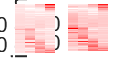

% emomap_topic_correlations(53,1)=0;
emomap_topic_correlations_zscores = zscore(emomap_topic_correlations);

% identify top 10% for each map
wh_topics = emomap_topic_correlations_zscores > prctile(emomap_topic_correlations_zscores, 90);

% only plot topics that are in top 10% for at least one map
wh_topics_to_plot = any(wh_topics, 2);

emomap_topic_correlations_selected = emomap_topic_correlations(wh_topics_to_plot, :);
emomap_topic_correlations_zscores_selected = emomap_topic_correlations_zscores(wh_topics_to_plot, :);

% **to do: put actual topic numbers on plot.  from: topicnum = topic_obj.metadata_table.TopicNumber
% **to do: reorder so that adjacent rows are most similar.  Rubinov/Sporns
% BCT toolbox has ways... [Mreordered,Mindices,cost] = reorder_matrix(M1,cost,flag)
 heatmap_topic_correlations(emomap_topic_correlations, names)

#### Report closest topic(s) to each Emotion map, with terms

----------------------------------------------
Reapp
----------------------------------------------


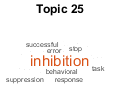

Topic 25
    {'inhibition,response,control,inhibitory,stop,task,motor,signal,activation,trials,'}
    {'nogo,suppression,responses,successful,inhibit,behavioral,error,inhibited,inhibit'}
    {'ing,pre,performance,prepotent,reactive,stopping,ability,sst,monitoring,suppress,'}
    {'correlates,gating,action,rifg,success,proactive,errors,tasks,required,participan'}
    {'ts,voluntary,behavior'                                                           }

 


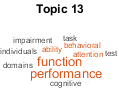

Topic 13
    {'cognitive,control,performance,task,executive,function,functions,cognition,abilit'}
    {'y,attention,behavioral,tasks,functioning,test,goal,effort,individuals,behavior,d'}
    {'emands,recruitment,abilities,lateral,performed,attentional,neuropsychological,di'}
    {'rected,domains,tests,level,individual,relevant,behavioural,evidence,speed,perfor'}
    {'ming,impairment,stroop,deficits,impaired,domain'                                 }

 


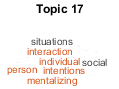

Topic 17
    {'social,empathy,participants,person,mentalizing,mental,people,mind,cognition,theo'}
    {'ry,perspective,interaction,game,behavior,interactions,junction,individual,attrib'}
    {'ution,human,empathic,interpersonal,situations,attachment,emotional,intentions,ta'}
    {'king,beliefs,understanding,affective,partner,exclusion,situation,activated,indiv'}
    {'iduals,ability,personal,socially,physical,intentional,cooperation'               }

 


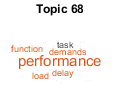

Topic 68
    {'memory,working,task,load,verbal,maintenance,performance,cognitive,activation,inf'}
    {'ormation,tasks,term,capacity,probe,manipulation,executive,spatial,phase,encoding'}
    {',updating,performed,storage,network,span,rehearsal,retention,increased,delay,fun'}
    {'ction,accuracy,functions,demands,vwm,delayed,phonological,loads,demand,performer'}
    {'s,sternberg,binding'                                                             }

 


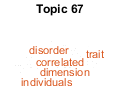

Topic 67
    {'personality,ocd,trait,traits,neuroticism,scores,anxiety,ec,compulsive,obsessive,'}
    {'alexithymia,psychopathy,disorder,individuals,extraversion,individual,dimension,d'}
    {'imensions,healthy,correlated,psychopathic,factor,correlates,temperament,emotiona'}
    {'l,eo,measures,questionnaire,affective,tas,disorders,dn,linked,scale,neurobiologi'}
    {'cal,conclusions,psychiatric,negatively,schizotypal,violent'                      }

 


----------------------------------------------
CommApr
----------------------------------------------


Topic 68
    {'memory,working,task,load,verbal,maintenance,performance,cognitive,activation,inf'}
    {'ormation,tasks,term,capacity,probe,manipulation,executive,spatial,phase,encoding'}
    {',updating,performed,storage,network,span,rehearsal,retention,increased,delay,fun'}
    {'ction,accuracy,functions,demands,vwm,delayed,phonological,loads,demand,performer'}
    {'s,sternberg,binding'                                                             }

 


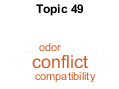

Topic 49
    {'conflict,interference,control,stroop,incongruent,task,response,congruent,olfacto'}
    {'ry,resolution,trials,odor,behavioral,attentional,color,cognitive,odors,simon,con'}
    {'gruency,word,flanker,effect,monitoring,irrelevant,processing,activated,conflicti'}
    {'ng,incompatible,neutral,relevant,mechanisms,detection,conflicts,situations,resol'}
    {'ve,adjustments,pre,compatibility,compatible,counting'                            }

 


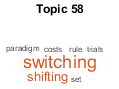

Topic 58
    {'switching,set,rule,task,switch,rules,flexibility,shifting,sets,sorting,trials,sh'}
    {'ift,shifts,anxiety,switches,card,wcst,anxious,costs,paradigm,single,ef,required,'}
    {'wisconsin,stimulus,trial,worry,repeat,switched,paradigms,execution,depending,com'}
    {'ponent,chunk,cost,gad,lower,updating,types,iu'                                   }

 


Topic 25
    {'inhibition,response,control,inhibitory,stop,task,motor,signal,activation,trials,'}
    {'nogo,suppression,responses,successful,inhibit,behavioral,error,inhibited,inhibit'}
    {'ing,pre,performance,prepotent,reactive,stopping,ability,sst,monitoring,suppress,'}
    {'correlates,gating,action,rifg,success,proactive,errors,tasks,required,participan'}
    {'ts,voluntary,behavior'                                                           }

 


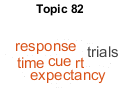

Topic 82
    {'trials,response,trial,stimulus,selection,task,cue,reaction,time,cues,target,rt,p'}
    {'reparation,times,competition,responses,increased,motor,event,pre,paradigm,faster'}
    {',preparatory,participants,required,speed,subsequent,expectancy,accuracy,demands,'}
    {'rts,indicating,anticipatory,expected,cued,role,instruction,current,preceded,phas'}
    {'e'                                                                               }

 


----------------------------------------------
NonModEmo
----------------------------------------------


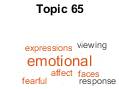

Topic 65
    {'faces,face,facial,expressions,processing,emotional,neutral,fearful,emotion,happy'}
    {',recognition,perception,expression,social,angry,response,responses,emotions,iden'}
    {'tity,fear,fg,sad,anger,affect,affective,viewing,signals,masked,matching,disgust,'}
    {'cues,viewed,behavioral,role,gender,threat,sensitivity,compared,people,trustworth'}
    {'iness'                                                                           }

 


Topic 68
    {'memory,working,task,load,verbal,maintenance,performance,cognitive,activation,inf'}
    {'ormation,tasks,term,capacity,probe,manipulation,executive,spatial,phase,encoding'}
    {',updating,performed,storage,network,span,rehearsal,retention,increased,delay,fun'}
    {'ction,accuracy,functions,demands,vwm,delayed,phonological,loads,demand,performer'}
    {'s,sternberg,binding'                                                             }

 


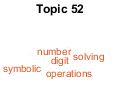

Topic 52
    {'sleep,number,numerical,numbers,arithmetic,sd,magnitude,calculation,deprivation,d'}
    {'igit,symbolic,mathematical,mental,distance,math,solving,rem,representation,multi'}
    {'plication,addition,wakefulness,comparison,retrieval,subtraction,numerosity,opera'}
    {'tions,night,counting,quantity,estimation,size,operation,single,digits,nonsymboli'}
    {'c,arabic,consolidation,symbols,solved,types'                                     }

 


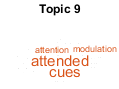

Topic 9
    {'attention,attentional,visual,spatial,search,orienting,target,top,selective,contr'}
    {'ol,location,areas,attended,network,stimulus,irrelevant,cues,distraction,shifts,r'}
    {'elevant,feature,modulation,task,cued,mechanisms,color,cueing,focus,bottom,proces'}
    {'sing,attend,event,endogenous,cue,attending,allocation,directed,resources,modulat'}
    {'ed,perceptual'                                                                   }

 


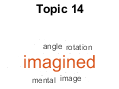

Topic 14
    {'wm,imagery,mental,imagined,rotation,mi,tasks,visual,visuospatial,motor,areas,spa'}
    {'tial,ltm,imagination,imagine,transformation,image,imagining,mentally,images,acti'}
    {'vated,ability,angle,degrees,physical,strategy,manipulation,visuo,poor,actual,rot'}
    {'ations,simulation,kinesthetic,gifted,representational,clock,angles,rehearsal,fut'}
    {'ure,instructed'                                                                  }

 


----------------------------------------------
ModEmo
----------------------------------------------


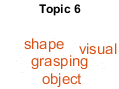

Topic 6
    {'object,objects,visual,shape,color,recognition,stream,shapes,areas,perception,act'}
    {'ivated,location,lateral,grasping,haptic,processing,texture,form,selective,colour'}
    {',properties,features,manipulation,orientation,grasp,participants,identification,'}
    {'visually,perceptual,reaching,viewing,naming,discrimination,size,matching,tools,k'}
    {'nowledge,intact,pathway,real'                                                    }

 


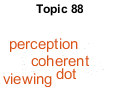

Topic 88
    {'motion,perception,visual,biological,areas,moving,processing,direction,dynamic,st'}
    {'atic,stimulus,human,illusion,sensitive,depth,perceptual,dot,cues,subjects,order,'}
    {'coherent,displays,illusory,perceived,viewing,stationary,dots,flow,form,percept,r'}
    {'andom,movement,optic,structure,figure,coherence,signals,experiments,shape,viewed'}

 


Topic 9
    {'attention,attentional,visual,spatial,search,orienting,target,top,selective,contr'}
    {'ol,location,areas,attended,network,stimulus,irrelevant,cues,distraction,shifts,r'}
    {'elevant,feature,modulation,task,cued,mechanisms,color,cueing,focus,bottom,proces'}
    {'sing,attend,event,endogenous,cue,attending,allocation,directed,resources,modulat'}
    {'ed,perceptual'                                                                   }

 


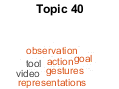

Topic 40
    {'action,actions,observation,mirror,motor,gestures,goal,imitation,tool,system,vide'}
    {'o,execution,areas,movements,directed,neuron,clips,observing,person,simulation,pe'}
    {'rformed,participants,gesture,human,understanding,actor,body,mns,videos,activated'}
    {',representations,goals,perception,intention,representation,tools,communicative,p'}
    {'lanning,aon,perspective'                                                         }

 


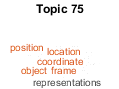

Topic 75
    {'spatial,space,location,virtual,navigation,representations,locations,position,rep'}
    {'resentation,orientation,reference,route,egocentric,object,participants,perspecti'}
    {'ve,environment,information,allocentric,frame,relative,coding,body,map,centered,v'}
    {'isuo,objects,neglect,coordinate,positions,judgments,goal,visual,relations,line,v'}
    {'isuospatial,frames,distance,reality,coordinates'                                 }

 



for i = 1:length(names)
    % For each emotion map

    wh = wh_topics(:, i);

    indx= find(wh); % topics to show

    % order them
    z = emomap_topic_correlations_zscores(wh, i);
    [zsort, zorder] = sort(z, 'descend');
    indx = indx(zorder);
    Topic_Index(i,:)=indx;
    
    printhdr(names{i})
 
    for j = 1:length(indx)

        [terms, WrapString] = get_topic_words(topic_obj, indx(j), true);
        termstr = [terms{:}];
        Terms{i,j}=termstr;

    end

end


% for i=1:4
%     for j=1:10
%     A= topic_obj.image_names(Topic_Index(i,j),:)
%     B=strsplit(A,'_');
%     C=strcat(B{3},',',B{4},',',B{5});
%     Related_Topic{i,j}=C;
%     end
% end



Top3words={'Inhibition','Cognitive control','Social_Empathy';
           'Working memory','Cognitive control','Conflict';
            'Emotion face','Math','Attention modulation';
            'Object recognition','Motion perception','Action observation'}

Top3words = 4×3 cell array
    {'Inhibition'        }    {'Cognitive control'}    {'Social_Empathy'      }
    {'Working memory'    }    {'Cognitive control'}    {'Conflict'            }
    {'Emotion face'      }    {'Math'             }    {'Attention modulation'}
    {'Object recognition'}    {'Motion perception'}    {'Action observation'  }



UnqiueTopic={'Inhibition','Reward_Decision','Math','Motion perception'}

UnqiueTopic = 1×4 cell array
    {'Inhibition'}    {'Reward_Decision'}    {'Math'}    {'Motion perception'}


----------------------------------------------
Reapp
----------------------------------------------


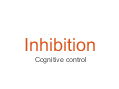

----------------------------------------------
CommApr
----------------------------------------------


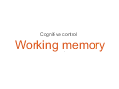

----------------------------------------------
NonModEmo
----------------------------------------------


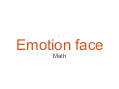

----------------------------------------------
ModEmo
----------------------------------------------


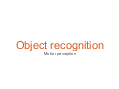


SIZEDATA=[10,8,7]; %%%% weight each topic
for i = 1:length(names)
    % For each emotion map
    printhdr(names{i})
    
    namestring2=Top3words(i,:)';

    figure;
    wordcloud(namestring2,SIZEDATA);
end

**Report most unique topic for each system component map**

Unique topic for every component. The larger discrepency between largest correlated (Normalized) region with the second largest correlated, the more unique is this topic.

for i=1:50
    [B I]=sort(emomap_topic_correlations_zscores(i,:),'descend');
     dis(i,1)=emomap_topic_correlations_zscores(i,I(1))-emomap_topic_correlations_zscores(i,I(2));
    
%     dis(i,1)=emomap_topic_correlations_zscores(i,I(1))-mean(emomap_topic_correlations_zscores(i,I(2:4)),2);
    
    dis(i,2)=I(1);
    dis(i,3)=i;
end

indexReappOnly=find(dis(:,2)==2);

Unique=sortrows(dis,1,'descend')

Unique =     3.6186    4.0000    5.0000
    3.3693    1.0000   17.0000
    3.3064    4.0000   44.0000
    2.1626    3.0000   31.0000
    2.1594    3.0000   48.0000
    1.9302    2.0000   23.0000
    1.8805    4.0000   47.0000
    1.8163    3.0000   28.0000
    1.8091    3.0000   25.0000
    1.8058    2.0000   34.0000


----------------------------------------------
Reapp
----------------------------------------------


Topic 25
    {'inhibition,response,control,inhibitory,stop,task,motor,signal,activation,trials,'}
    {'nogo,suppression,responses,successful,inhibit,behavioral,error,inhibited,inhibit'}
    {'ing,pre,performance,prepotent,reactive,stopping,ability,sst,monitoring,suppress,'}
    {'correlates,gating,action,rifg,success,proactive,errors,tasks,required,participan'}
    {'ts,voluntary,behavior'                                                           }

 


----------------------------------------------
CommApr
----------------------------------------------


Topic 49
    {'conflict,interference,control,stroop,incongruent,task,response,congruent,olfacto'}
    {'ry,resolution,trials,odor,behavioral,attentional,color,cognitive,odors,simon,con'}
    {'gruency,word,flanker,effect,monitoring,irrelevant,processing,activated,conflicti'}
    {'ng,incompatible,neutral,relevant,mechanisms,detection,conflicts,situations,resol'}
    {'ve,adjustments,pre,compatibility,compatible,counting'                            }

 


----------------------------------------------
NonModEmo
----------------------------------------------


Topic 65
    {'faces,face,facial,expressions,processing,emotional,neutral,fearful,emotion,happy'}
    {',recognition,perception,expression,social,angry,response,responses,emotions,iden'}
    {'tity,fear,fg,sad,anger,affect,affective,viewing,signals,masked,matching,disgust,'}
    {'cues,viewed,behavioral,role,gender,threat,sensitivity,compared,people,trustworth'}
    {'iness'                                                                           }

 


----------------------------------------------
ModEmo
----------------------------------------------


Topic 6
    {'object,objects,visual,shape,color,recognition,stream,shapes,areas,perception,act'}
    {'ivated,location,lateral,grasping,haptic,processing,texture,form,selective,colour'}
    {',properties,features,manipulation,orientation,grasp,participants,identification,'}
    {'visually,perceptual,reaching,viewing,naming,discrimination,size,matching,tools,k'}
    {'nowledge,intact,pathway,real'                                                    }

 


for i=1:4
    
    A=find(Unique(:,2)==i);
    id_Uniq(i)=Unique(A(1),3); % find the top 1
end 

for i = 1:length(names)
    % For each emotion map
    printhdr(names{i})
        [terms, WrapString] = get_topic_words(topic_obj, id_Uniq(i), true);
end

**Plot top 5 topics for each BF map using work cloud**

----------------------------------------------
Reapp
----------------------------------------------


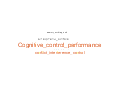

----------------------------------------------
CommApr
----------------------------------------------


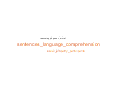

----------------------------------------------
NonModEmo
----------------------------------------------


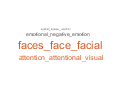

----------------------------------------------
ModEmo
----------------------------------------------


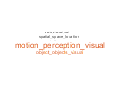

[a namestring c]=xlsread('D:\CANlab_Working\ResultPPT\Neurosynth result2.xlsx');
namestring{2:6,:};
SIZEDATA=[10,8,7,6,5]; %%%% weight each topic
for i = 1:length(names)
    % For each emotion map
    printhdr(names{i})
    
    namestring2=namestring(2:6,i)';

    figure;
    wordcloud(namestring2,SIZEDATA);
%     title(sprintf('Topic %d\n', namestring{1,i}))
end

### ** Reduced force-directed graph** 

Restrict to subset of topics with top-10% associations for at least one emotion map

****TO DO******

% wh_topics = any(full(stats.C(:, end-3:end)) > 0, 2);  % Topics with any significant positive association with Emo maps
% 
% wh_topics(end-3:end) = 1; % save Emo maps of course
% 
% topic_obj_reduced = get_wh_image(topic_obj_plus, wh_topics);
% 
% ntopics = sum(wh_topics(1:end-4));
% colorpartitions = {[1:ntopics] [ntopics+1] [ntopics+2] [ntopics+3] [ntopics+4]};
% sizes = [6 * ones(ntopics, 1); 10; 10; 10; 10];
% 
% labels(~wh_topics) = [];
% 
% [stats, handles] = canlab_force_directed_graph(topic_obj_reduced.dat, 'connectmetric', 'partial_corr', ...
%     'partitions', colorpartitions, 'partitioncolors', partitioncolors, ...
%     'sizescale', 'custom', 'sizes', sizes, 'names', labels);
% 
% delete(handles.lh_neg)  % delete lines with negative associations, if any



[coeff, score, latent, tsquared, explained, mu] =pca(emomap_topic_correlations_zscores)

coeff =     0.6294    0.0696    0.5020   -0.5891
    0.5920    0.3847    0.0344    0.7073
   -0.0787    0.8209   -0.4368   -0.3593
   -0.4972    0.4163    0.7457    0.1535


score =    -1.3979   -1.2461    0.7807    0.2906
    0.1514   -0.7286    0.0698   -0.2258
    0.4855   -0.2898    0.1523   -0.7572
   -0.0390   -0.9352   -0.1058   -0.3957
   -3.4545    1.8557    2.3555    0.2704
   -0.1639   -0.9972   -0.1768   -0.1590
   -1.4725    2.4592    0.3339    0.0117
    1.7618    0.2449    0.6606   -0.7771
   -0.3334    1.9435   -0.3650    0.0058
    0.4500    0.7931   -0.2314    0.6811


latent =     1.7922
    1.2235
    0.6044
    0.3799


tsquared =     3.5901
    0.5889
    1.7480
    1.1464
   18.8452
    0.9460
    6.3376
    4.0926
    3.3697
    1.9370


explained =    44.8047
   30.5880
   15.1104
    9.4969


mu = 1.0e-15 *

   -0.1110   -0.0089   -0.0400   -0.0444


coeff(:,1)*score(:,1)'

ans =    -0.8798    0.0953    0.3056   -0.0245   -2.1742   -0.1031   -0.9268    1.1088   -0.2098    0.2833    1.2001    0.3524    0.0961    0.1147   -0.1228    0.4044    2.7947    0.1439    0.6309    0.2484   -1.2022   -0.0040    1.0075   -0.3357   -0.0698    0.0275    1.1627   -0.2585   -0.4524    0.1324   -0.8030    0.0799    0.3703    1.9443   -0.6260   -0.7257   -1.2012    0.4762    0.0812    0.3302    0.6914   -0.2978    0.5511   -1.3397    0.1194   -0.7089   -1.3969   -0.3626   -0.2071   -0.3200
   -0.8276    0.0896    0.2874   -0.0231   -2.0452   -0.0970   -0.8718    1.0430   -0.1974    0.2664    1.1289    0.3315    0.0904    0.1079   -0.1155    0.3804    2.6289    0.1354    0.5935    0.2337   -1.1309   -0.0037    0.9477   -0.3158   -0.0656    0.0259    1.0937   -0.2431   -0.4256    0.1246   -0.7553    0.0751    0.3484    1.8289   -0.5888   -0.6826   -1.1299    0.4480    0.0764    0.3106    0.6504   -0.2801    0.5184   -1.2602    0.1123   -0.6668   -1.3140   -0.3411   -0.1948   


x = score(:,1);
y = score(:,2);
dot_names = {'A', 'B', 'C', 'D', 'E'};

[a b c]=xlsread('C:\Users\KeBo\Dropbox (Dartmouth College)\2021_Ke_Bo_reappraisal_Gianaros\Data\Supplement result\TopicMap','Sheet3')

a =            0         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         498
           2         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         NaN         Na

b = 51×42 cell array
    {'Topic GPT'                }    {'Topic number'}    {0×0 char        }    {0×0 char          }    {0×0 char             }    {0×0 char          }    {0×0 char         }    {0×0 char        }    {0×0 char        }    {0×0 char        }    {0×0 char          }    {0×0 char            }    {0×0 char        }    {0×0 char         }    {0×0 char          }    {0×0 char        }    {0×0 char           }    {0×0 char           }    {0×0 char         }    {0×0 char           }    {0×0 char           }    {0×0 char        }    {0×0 char           }    {0×0 char           }    {0×0 char         }    {0×0 char           }    {0×0 char               }    {0×0 char            }    {0×0 char              }    {0×0 char          }    {0×0 char         }    {0×0 char               }    {0×0 char            }    {0×0 char               }    {0×0 char           }    {0×0 char         }    {0×0 char             }    {0×0 char         }    {0×0 char          }    {0×0 char       

c = 51×43 cell array
    {'Topic GPT'                }    {'Topic number'}    {[           NaN]}    {[             NaN]}    {[            NaN]}    {[          NaN]}    {[            NaN]}    {[           NaN]}    {[           NaN]}    {[          NaN]}    {[             NaN]}    {[               NaN]}    {[           NaN]}    {[           NaN]}    {[            NaN]}    {[           NaN]}    {[              NaN]}    {[              NaN]}    {[           NaN]}    {[           NaN]}    {[          NaN]}    {[           NaN]}    {[              NaN]}    {[          NaN]}    {[            NaN]}    {[              NaN]}    {[                  NaN]}    {[             NaN]}    {[                 NaN]}    {[             NaN]}    {[            NaN]}    {[                  NaN]}    {[            NaN]}    {[                  NaN]}    {[              NaN]}    {[            NaN]}    {[                NaN]}    {[            NaN]}    {[           NaN]}    {[           NaN]}    {[           NaN]}    {

dot_names=c(2:51,2);
figure;
scatter(x, y, 'filled');
hold on;

% [coeff(1,1),coeff(1,2)]

ans =     0.6294    0.0696


% [coeff(2,1),coeff(2,2)]

ans =     0.5920    0.3847


% 
% [coeff(3,1),coeff(3,2)]

ans =    -0.0787    0.8209


% [coeff(4,1),coeff(4,2)]

ans =    -0.4972    0.4163


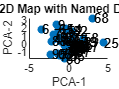


for i = 1:length(x)
    text(x(i) + 0.1, y(i), num2str(dot_names{i}));
end
for i = 1:length(x)
    text(x(i) + 0.1, y(i), num2str(dot_names{i}));
end

xlabel('PCA-1');
ylabel('PCA-2');
title('2D Map with Named Dots');
hold off;

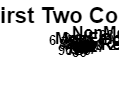



% Combine the four 52-by-1 vectors into a single 52-by-4 matrix
dataMatrix = zscore(emomap_topic_correlations_zscores);

% Perform PCA on the data matrix
[coeff, score, ~, ~, explained] = pca(dataMatrix);

% Select the first two principal components
firstTwoComponents = score(:, 1:2);

% Plot the first two principal components on a 2D map
figure;
% scatter(firstTwoComponents(:, 1), firstTwoComponents(:, 2));
% xlabel('First Principal Component');
% ylabel('Second Principal Component');
% title('PCA: First Two Components');
grid on;



biplot_scaling = max(max(abs(score(:, 1:2)))) / max(max(abs(coeff(:, 1:2))));
scaledFirstTwoComponents = firstTwoComponents / biplot_scaling;
x= scaledFirstTwoComponents(:, 1);
y= scaledFirstTwoComponents(:, 2);

% figure;
% scatter(scaledFirstTwoComponents(:, 1), scaledFirstTwoComponents(:, 2));
% scatter(coeff(:, 1), coeff(:, 2),25,'r','filled');
xlabel('First Principal Component');
ylabel('Second Principal Component');
title('PCA: First Two Components');
hold on


for i = 1:length(x)
    text(x(i) + 0.01, y(i), num2str(dot_names{i}),'FontSize',10,'FontWeight','bold');
end

for i = 1:4
    text(coeff(i, 1) + 0.01, coeff(i, 2), names(i),'FontSize',12,'FontWeight','bold');

end
axis([-0.8 0.8 -0.8 0.8])

% Draw x and y axes
% xlims = get(gca, 'XLim');
% ylims = get(gca, 'YLim');
% hold on;
% line(xlims, [0 0], 'Color', 'k', 'LineWidth', 0.8);
% line([0 0], ylims, 'Color', 'k', 'LineWidth', 0.8);
hold off;
axis off
set(gca,'fontweight','bold','fontsize',15)

% Plot the biplot with the first two principal components and original variables



%%%%PCA1 pos %%%%

PCA1_Pos=find(score(:,1)>0);
reconstruct_image(topic_obj)

ans = ans(:,:,1,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

% [voldata, vectorized_voldata, xyz_coord_struct] =reconstruct_image(topic_obj);
 fname='D:\CANlab_Working\CANlab_Note\Topic map\Topic54_forward_TorCode.nii'

fname = 'D:\CANlab_Working\CANlab_Note\Topic map\Topic54_forward_TorCode.nii'

write(topic_obj_forwardinference, 'fname', fname, 'overwrite');

Writing: 
D:\CANlab_Working\CANlab_Note\Topic map\Topic54_forward_TorCode.nii


 fname='D:\CANlab_Working\CANlab_Note\Topic map\Topic54_reverse_TorCode.nii'

fname = 'D:\CANlab_Working\CANlab_Note\Topic map\Topic54_reverse_TorCode.nii'

write(topic_obj_reverseinference, 'fname', fname, 'overwrite');

Writing: 
D:\CANlab_Working\CANlab_Note\Topic map\Topic54_reverse_TorCode.nii



PCA1_PosWeight=score(PCA1_Pos,1);
[B I]=sort(PCA1_PosWeight,'descend');
PCA1_PosWeight=PCA1_PosWeight(I(1:5));
PCA1_Pos=PCA1_Pos(I(1:5));
PCA1_PosWeight=PCA1_PosWeight/sum(PCA1_PosWeight);
PCA1Pos_mat=topic_obj.dat(:,PCA1_Pos)*PCA1_PosWeight;
temp=BF_tstat1_CC;
temp.dat=PCA1Pos_mat;
figure
surface(temp)

ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [1.4142 -8.6596e-17 0]
     Visible: on

  Show all properties


Anatomical image: Adapted from the 7T high-resolution atlas of Keuken, Forstmann et al.                                                                                                                                             
Keuken et al. (2014). Quantifying inter-individual anatomical variability in the subcortex using 7T structural MRI.                                                                                                                 
Forstmann, Birte U., Max C. Keuken, Andreas Schafer, Pierre-Louis Bazin, Anneke Alkemade, and Robert Turner. 2014. ?Multi-Modal Ultra-High Resolution Structural 7-Tesla MRI Data Repository.? Scientific Data 1 (December): 140050.


ans =   1×8 Patch array:

    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch


t2 = threshold(temp, [2 inf],'raw-between')

Keeping vals between 2.000 and Inf: 1381 voxels in .sig


t2 =   statistic_image with properties:

              type: 'BF'
                 p: []
            p_type: '2-tailed P-value from input dfe'
               ste: [51052×1 single]
         threshold: []
          thr_type: []
               sig: [51052×1 logical]
                 N: [51052×1 single]
               dfe: 181
      image_labels: {}
               dat: [51052×1 double]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [242868×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed 191816 empty voxels and   0 empty images'}


surface(t2)

ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [1.4142 -8.6596e-17 0]
     Visible: on

  Show all properties


Anatomical image: Adapted from the 7T high-resolution atlas of Keuken, Forstmann et al.                                                                                                                                             
Keuken et al. (2014). Quantifying inter-individual anatomical variability in the subcortex using 7T structural MRI.                                                                                                                 
Forstmann, Birte U., Max C. Keuken, Andreas Schafer, Pierre-Louis Bazin, Anneke Alkemade, and Robert Turner. 2014. ?Multi-Modal Ultra-High Resolution Structural 7-Tesla MRI Data Repository.? Scientific Data 1 (December): 140050.


ans =   1×8 Patch array:

    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch


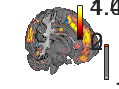

ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [0 0 1.2643]
     Visible: on

  Show all properties


lightRestoreSingle 

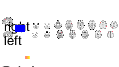

Setting up fmridisplay objects
sagittal montage:   7 voxels displayed, 1374 not displayed on these slices
sagittal montage:   5 voxels displayed, 1376 not displayed on these slices
sagittal montage:  14 voxels displayed, 1367 not displayed on these slices
axial montage: 192 voxels displayed, 1189 not displayed on these slices
axial montage: 215 voxels displayed, 1166 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: 'C:\Users\KeBo\Documents\GitHub\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


figure
montage(t2)

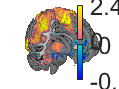

ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [1.4142 -8.6596e-17 0]
     Visible: on

  Show all properties


Anatomical image: Adapted from the 7T high-resolution atlas of Keuken, Forstmann et al.                                                                                                                                             
Keuken et al. (2014). Quantifying inter-individual anatomical variability in the subcortex using 7T structural MRI.                                                                                                                 
Forstmann, Birte U., Max C. Keuken, Andreas Schafer, Pierre-Louis Bazin, Anneke Alkemade, and Robert Turner. 2014. ?Multi-Modal Ultra-High Resolution Structural 7-Tesla MRI Data Repository.? Scientific Data 1 (December): 140050.


ans =   1×8 Patch array:

    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch


%%%%%PCA1 neg %%%%
PCA1_Neg=find(score(:,1)<0);
PCA1_NegWeight=score(PCA1_Neg,1);
[B I]=sort(PCA1_NegWeight,'ascend');
PCA1_NegWeight=PCA1_NegWeight(I(1:5));
PCA1_Neg=PCA1_Neg(I(1:5));

PCA1_NegWeight=PCA1_NegWeight/sum(PCA1_NegWeight);
PCA1Neg_mat=topic_obj.dat(:,PCA1_Neg)*PCA1_NegWeight;
temp=BF_tstat1_CC;
temp.dat=PCA1Neg_mat;
figure
surface(temp)

figure
t2 = threshold(temp, [2 inf],'raw-between')

Keeping vals between 2.000 and Inf: 12531 voxels in .sig


t2 =   statistic_image with properties:

              type: 'BF'
                 p: []
            p_type: '2-tailed P-value from input dfe'
               ste: [91164×1 single]
         threshold: []
          thr_type: []
               sig: [91164×1 logical]
                 N: [91164×1 single]
               dfe: 181
      image_labels: {}
               dat: [91164×1 double]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [242868×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed 151704 empty voxels and   0 empty images'}


surface(t2)

ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [1.4142 -8.6596e-17 0]
     Visible: on

  Show all properties


Anatomical image: Adapted from the 7T high-resolution atlas of Keuken, Forstmann et al.                                                                                                                                             
Keuken et al. (2014). Quantifying inter-individual anatomical variability in the subcortex using 7T structural MRI.                                                                                                                 
Forstmann, Birte U., Max C. Keuken, Andreas Schafer, Pierre-Louis Bazin, Anneke Alkemade, and Robert Turner. 2014. ?Multi-Modal Ultra-High Resolution Structural 7-Tesla MRI Data Repository.? Scientific Data 1 (December): 140050.


ans =   1×8 Patch array:

    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch


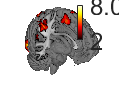

ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [0 0 1.2643]
     Visible: on

  Show all properties


lightRestoreSingle

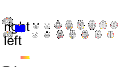

Setting up fmridisplay objects
sagittal montage: 115 voxels displayed, 12416 not displayed on these slices
sagittal montage:  95 voxels displayed, 12436 not displayed on these slices
sagittal montage:  99 voxels displayed, 12432 not displayed on these slices
axial montage: 1243 voxels displayed, 11288 not displayed on these slices
axial montage: 1467 voxels displayed, 11064 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: 'C:\Users\KeBo\Documents\GitHub\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


figure
montage(t2)

%%%%PCA2 pos %%%%
PCA2_Pos=find(score(:,2)>0);
PCA2_PosWeight=score(PCA2_Pos,2);

[B I]=sort(PCA2_PosWeight,'descend');
PCA2_PosWeight=PCA2_PosWeight(I(1:5));
PCA2_Pos=PCA2_Pos(I(1:5));


PCA2_PosWeight=PCA2_PosWeight/sum(PCA2_PosWeight);
PCA2Pos_mat=topic_obj.dat(:,PCA2_Pos)*PCA2_PosWeight;
temp=BF_tstat1_CC;
temp.dat=PCA2Pos_mat;
figure
surface(temp)

ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [1.4142 -8.6596e-17 0]
     Visible: on

  Show all properties


Anatomical image: Adapted from the 7T high-resolution atlas of Keuken, Forstmann et al.                                                                                                                                             
Keuken et al. (2014). Quantifying inter-individual anatomical variability in the subcortex using 7T structural MRI.                                                                                                                 
Forstmann, Birte U., Max C. Keuken, Andreas Schafer, Pierre-Louis Bazin, Anneke Alkemade, and Robert Turner. 2014. ?Multi-Modal Ultra-High Resolution Structural 7-Tesla MRI Data Repository.? Scientific Data 1 (December): 140050.


ans =   1×8 Patch array:

    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch


t2 = threshold(temp, [2 inf],'raw-between')

Keeping vals between 2.000 and Inf: 7222 voxels in .sig


t2 =   statistic_image with properties:

              type: 'BF'
                 p: []
            p_type: '2-tailed P-value from input dfe'
               ste: [64644×1 single]
         threshold: []
          thr_type: []
               sig: [64644×1 logical]
                 N: [64644×1 single]
               dfe: 181
      image_labels: {}
               dat: [64644×1 double]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [242868×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed 178224 empty voxels and   0 empty images'}


surface(t2)

ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [1.4142 -8.6596e-17 0]
     Visible: on

  Show all properties


Anatomical image: Adapted from the 7T high-resolution atlas of Keuken, Forstmann et al.                                                                                                                                             
Keuken et al. (2014). Quantifying inter-individual anatomical variability in the subcortex using 7T structural MRI.                                                                                                                 
Forstmann, Birte U., Max C. Keuken, Andreas Schafer, Pierre-Louis Bazin, Anneke Alkemade, and Robert Turner. 2014. ?Multi-Modal Ultra-High Resolution Structural 7-Tesla MRI Data Repository.? Scientific Data 1 (December): 140050.


ans =   1×8 Patch array:

    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch


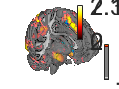

ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [0 0 1.2643]
     Visible: on

  Show all properties


lightRestoreSingle 

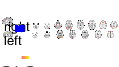

Setting up fmridisplay objects
sagittal montage:  58 voxels displayed, 7164 not displayed on these slices
sagittal montage:  32 voxels displayed, 7190 not displayed on these slices
sagittal montage:  51 voxels displayed, 7171 not displayed on these slices
axial montage: 860 voxels displayed, 6362 not displayed on these slices
axial montage: 1088 voxels displayed, 6134 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: 'C:\Users\KeBo\Documents\GitHub\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


figure
montage(t2)

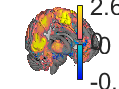

ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [1.4142 -8.6596e-17 0]
     Visible: on

  Show all properties


Anatomical image: Adapted from the 7T high-resolution atlas of Keuken, Forstmann et al.                                                                                                                                             
Keuken et al. (2014). Quantifying inter-individual anatomical variability in the subcortex using 7T structural MRI.                                                                                                                 
Forstmann, Birte U., Max C. Keuken, Andreas Schafer, Pierre-Louis Bazin, Anneke Alkemade, and Robert Turner. 2014. ?Multi-Modal Ultra-High Resolution Structural 7-Tesla MRI Data Repository.? Scientific Data 1 (December): 140050.


ans =   1×8 Patch array:

    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch


%%%%%PCA2 neg %%%%
PCA2_Neg=find(score(:,2)<0);
PCA2_NegWeight=score(PCA2_Neg,2);

[B I]=sort(PCA2_NegWeight,'ascend');
PCA2_NegWeight=PCA2_NegWeight(I(1:5));
PCA2_Neg=PCA2_Neg(I(1:5));

PCA2_NegWeight=PCA2_NegWeight/sum(PCA2_NegWeight);
PCA2Neg_mat=topic_obj.dat(:,PCA2_Neg)*PCA2_NegWeight;
temp=BF_tstat1_CC;
temp.dat=PCA2Neg_mat;
figure
surface(temp)

figure
t2 = threshold(temp, [2 inf],'raw-between')

Keeping vals between 2.000 and Inf: 17099 voxels in .sig


t2 =   statistic_image with properties:

              type: 'BF'
                 p: []
            p_type: '2-tailed P-value from input dfe'
               ste: [108640×1 single]
         threshold: []
          thr_type: []
               sig: [108640×1 logical]
                 N: [108640×1 single]
               dfe: 181
      image_labels: {}
               dat: [108640×1 double]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [242868×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed 134228 empty voxels and   0 empty images'}


surface(t2)

ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [1.4142 -8.6596e-17 0]
     Visible: on

  Show all properties


Anatomical image: Adapted from the 7T high-resolution atlas of Keuken, Forstmann et al.                                                                                                                                             
Keuken et al. (2014). Quantifying inter-individual anatomical variability in the subcortex using 7T structural MRI.                                                                                                                 
Forstmann, Birte U., Max C. Keuken, Andreas Schafer, Pierre-Louis Bazin, Anneke Alkemade, and Robert Turner. 2014. ?Multi-Modal Ultra-High Resolution Structural 7-Tesla MRI Data Repository.? Scientific Data 1 (December): 140050.


ans =   1×8 Patch array:

    Patch    Patch    Patch    Patch    Patch    Patch    Patch    Patch


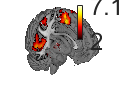

ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [0 0 1.2643]
     Visible: on

  Show all properties


lightRestoreSingle

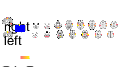

Setting up fmridisplay objects
sagittal montage: 203 voxels displayed, 16896 not displayed on these slices
sagittal montage: 238 voxels displayed, 16861 not displayed on these slices
sagittal montage: 191 voxels displayed, 16908 not displayed on these slices
axial montage: 2231 voxels displayed, 14868 not displayed on these slices
axial montage: 2403 voxels displayed, 14696 not displayed on these slices


ans =   fmridisplay with properties:

            overlay: 'C:\Users\KeBo\Documents\GitHub\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\keuken_2014_enhanced_for_underlay.img'
              SPACE: [1×1 struct]
    activation_maps: {[1×1 struct]}
            montage: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
            surface: {}
          orthviews: {}
            history: {}
    history_descrip: []
    additional_info: ''


figure
montage(t2)

Subregions:

savefilename = 'Final_CC_Combined_001_3mm_Multiply_BF_4_6_WithoutRest3_Beta_WithoutSTS_NewBase_CC15.mat';
 
load(fullfile(datadir, savefilename))

% figure
% montage(BF_tstat2_CC)
Reappraisal_Only_Sub=region(BF_tstat2_CC);

Grouping contiguous voxels:  16 regions



region2fmri_data(Reappraisal_Only_Sub,BF_tstat2_CC)

ans =   statistic_image with properties:

              type: 'BF'
                 p: []
            p_type: '2-tailed P-value from input dfe'
               ste: [242868×1 single]
         threshold: []
          thr_type: []
               sig: [242868×1 logical]
                 N: [242868×1 single]
               dfe: 181
      image_labels: {}
               dat: [242868×1 double]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: 0
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'}


for i=1:16
    fmri_data(Reappraisal_Only_Sub(i))
    canlab_pattern_similarity(region2fmri_data(Reappraisal_Only_Sub(i),BF_tstat2_CC),topic_obj.dat,'correlation') 
end

Using default mask: C:\Users\KeBo\Documents\GitHub\CanlabCore\CanlabCore\canlab_canonical_brains\Canonical_brains_surfaces\brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


Error using deblank
Input should be a string, character array, or cell array of character arrays.

Error in fmri_data (line 550)
                space_defining_image = deblank(image_names(1, :));

## Subfunctions

function heatmap_topic_correlations(emomap_topic_correlations, names)

emomap_topic_correlations_zscores = zscore(emomap_topic_correlations);
 
% reorder using Sporns BCT
corrmat = corr([emomap_topic_correlations'; emomap_topic_correlations_zscores']); % 2nd order correlation mat, for resorting
[~,Mindices] = reorder_matrix(corrmat,'line', false);

emomap_topic_correlations = emomap_topic_correlations(Mindices, :);
emomap_topic_correlations_zscores = emomap_topic_correlations_zscores(Mindices, :);
% ***don't forget to reorder topic numbers!***

create_figure('Correlation profiles', 1, 2)
imagesc(emomap_topic_correlations)
set(gca, 'XTick', 1:length(names), 'XTickLabel', names, 'XTickLabelRotation', 45);
% set(gca, 'YTick', 1:size(emomap_topic_correlations, 1), 'YDir', 'Reverse')
set(gca, 'YDir', 'Reverse','FontSize',16)

ylabel('Topic number')
title('Spatial correlations')
axis tight

subplot(1, 2, 2)
imagesc(emomap_topic_correlations_zscores)
set(gca, 'XTick', 1:length(names), 'XTickLabel', names, 'XTickLabelRotation', 45);
% set(gca, 'YTick', 1:size(emomap_topic_correlations, 1), 'YDir', 'Reverse')
set(gca, 'YDir', 'Reverse','FontSize',16)
ylabel('Topic number')
title('Spatial correlations')
axis tight

% colormap hot
cm = colormap_tor([1 1 1], [1 0 0]);
colormap(cm)
drawnow

end % heatmap function



function line_plot_topic_correlations(emomap_topic_correlations, colors, names)

emomap_topic_correlations_zscores = zscore(emomap_topic_correlations);

create_figure('Correlation profiles', 2, 1)
for i = 1:size(emomap_topic_correlations, 2)
    plot(emomap_topic_correlations(:, i), '-o', 'color', colors{i}, 'MarkerFaceColor', colors{i} ./ 1.2,  'LineWidth', 3);
end

xlabel('Topic number')
ylabel('Correlation')
legend(names)
title('Spatial correlations')
axis tight


subplot(2, 1, 2)
for i = 1:size(emomap_topic_correlations, 2)
    plot(emomap_topic_correlations_zscores(:, i), '-o', 'color', colors{i}, 'MarkerFaceColor', colors{i} ./ 1.2, 'LineWidth', 3);
end

xlabel('Topic number')
ylabel('Correlation (z-score)')
legend(names)
title('Spatial correlations')
axis tight

end % line_plot function


function [terms, WrapString] = get_topic_words(topic_obj, indx, doplot)

topicnum = table2array(topic_obj.metadata_table(indx, 1));

terms = table2array(topic_obj.metadata_table(indx, 2:end-1));

if doplot
    figure;
    wordcloud(terms)
    title(sprintf('Topic %d\n', topicnum))
end

termstr = [terms{:}];

WrapString = textwrap({termstr}, 80);

if doplot
    fprintf('Topic %d\n', topicnum)

    disp(WrapString)

    disp(' ')
end

end % get_topic_words

